%% AAE 532 HW 5 Problem 2
% Tomoki Koike
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Fall\AAE532\matlab\outputs\ps5';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
format longG;

% Set constants
planet_consts = setup_planetary_constants();  % Function that sets up all the constants in the table 
sun = planet_consts.sun;  % structure of sun
earth = planet_consts.earth;  % structure of earth
mars = planet_consts.mars;  % structure of mars
G = 6.6743015e-20;  % Gravitational constant [km^3/kg/s^2]

% (a) Calculate parameters
rp = 1.5*mars.mer;  % radius of periapsis
ra = 6.5*mars.mer;  % radius of apoapsis 
M = -90;  % mean anomaly
a = 0.5*(rp + ra);  % semi major axis
e = (ra - rp) / (ra + rp);  % eccentricity
p = a * (1 - e^2);  % semi latus rectum
mu = mars.gp;  % gravitational parameter
h = sqrt(mu * p);  % specific angular momentum 
IP = 2 * pi * sqrt(a^3 / mu);  % period
IP_days = IP / 60 / 60 / 24;  % period in days
En = -mu / 2 / a;  % specific energy 
E = rad2deg(M2E_anomaly(M, e, "deg"))  % eccentric anomaly

E =          -120.769115189563


E0 = E;
E = 360 + E

E =           239.230884810437


TA = E2T_anomaly(e,E,"deg")  % true anomaly

TA =           210.546537097162


r = p / (1 + e * cosd(TA))  % position

r =           17932.5912422288


v = vis_viva(r, a, mu)  % velocity

v =           1.27462454110073


gamma = -acosd(h / r / v)  % flight path angle

gamma =          -34.5256071562967


del_t = deg2rad(M + 360) * sqrt(a^3 / mu)  % time elapse

del_t =           36066.9110439507


del_t_day = del_t / 60 / 60 / 24

del_t_day =          0.417441100045725


% (b)
r0vec = r * [cosd(TA), sind(TA)];

r0vec =          -15443.8459875661         -9114.02489426051


v0vec = v * [cosd(TA + 90 + abs(gamma)), sind(TA + 90 + abs(gamma))];

v0vec =           1.15587951219096        -0.537224603004596


% (c)
Mf = 90;
Ef = rad2deg(M2E_anomaly(Mf, e, "deg"));

Ef =           120.769115189563


TAf = E2T_anomaly(e, Ef, "deg");

TAf =           149.453462902838


rfmag = p / (1 + e * cosd(TAf));

rfmag =           17932.5912422288


[rfvec, vfvec, f, g, fdot, gdot] = FandG_elp(a, mu, deg2rad(Ef-E0), 0.5*IP, r0vec, v0vec);

rfvec =          -15443.8460343113          9114.02491598655


vfvec =          -1.15587950557771        -0.537224603004596


f =         -0.118837968895521


g =          -14948.9294871715


fdot =       6.59497081608159e-05


gdot =         -0.118837965694861


[rfvec2, vfvec2, f2, g2, fdot2, gdot2] = FandG_conic(p, mu, deg2rad(TAf-(TA-360)),r0vec,v0vec,rfmag);

rfvec2 =           -15443.845987566          9114.02489426052


vfvec2 =          -1.15587951219096        -0.537224603004596


f2 =         -0.118837968895521


g2 =          -14948.9294467303


fdot2 =       6.59497083494782e-05


gdot2 =         -0.118837968895521


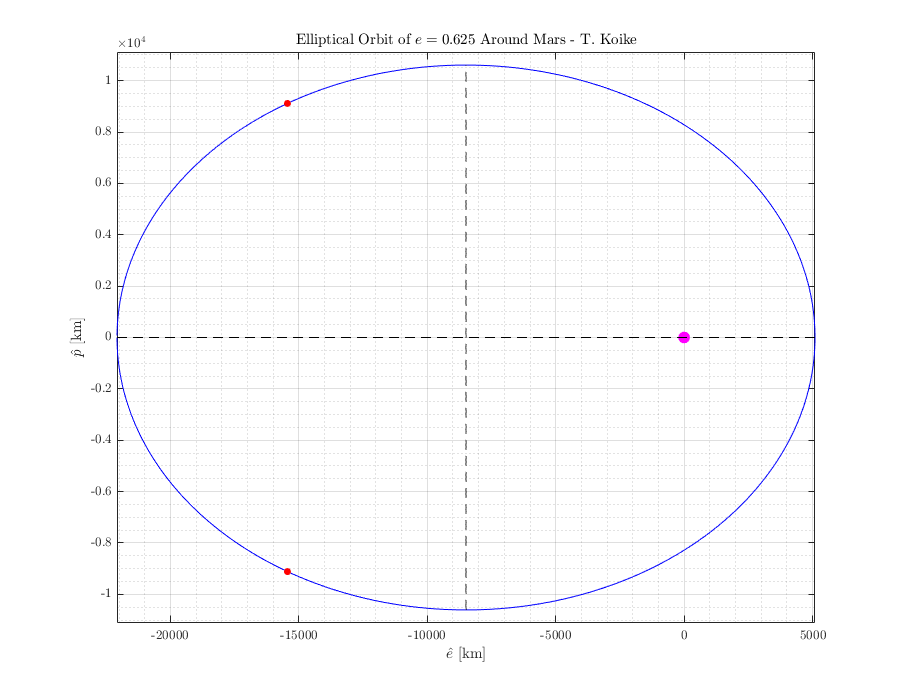

% (d)
Th = -pi:0.01:pi;
R = p ./ (1 + e * cos(Th)); X = R .* cos(Th); Y = R .* sin(Th);
fig = figure("Renderer","painters", "Position",[10 10 900 700]);
    plot(X, Y, '-b')
    title('Elliptical Orbit of $e=0.625$ Around Mars - T. Koike')
    hold on; grid on; grid minor; box on; axis equal;
    plot(r*cosd(TA), r*sind(TA), '.r', 'MarkerSize', 18)
    plot(rfmag*cosd(TAf), rfmag*sind(TAf), '.r', 'MarkerSize', 18)
    % Mars
    plot(0, 0, '.m', 'MarkerSize', 30)
    % Axes
    nanikore = -ra:rp; korenani = -a*sqrt(1-e^2):a*sqrt(1-e^2);
    plot(nanikore, zeros(size(nanikore)), '--k')
    plot(-a*e*ones(size(korenani)), korenani, '--k')
    hold off
    xlabel('$\hat{e}$ [km]')
    ylabel('$\hat{p}$ [km]')

saveas(fig, fullfile(fdir, 'p2_orbit.png'));